%cleaning workspace
clear;

% Load dataset
load Dataset_task2.mat;
%Fix missing data in dataset, remove column 19 since is the duplicate of the 18
short_matrix_no_id(:,19) = [];
short_matrix_no_id = fillmissing(short_matrix_no_id,"knn");
%split type of day in 3 boolean column
%[sun=0, rain=1, snow=2]
type_of_day = dummyvar(short_matrix_no_id(:, 16) + 1);
short_matrix_no_id(:,16) = [];
%concat type of day at the end of the dataset
short_matrix_no_id = [short_matrix_no_id, type_of_day];

%NORMALIZE DATA
short_matrix_no_id(:,[2:5,9:14,17]) = normalize(short_matrix_no_id(:,[2:5,9:14,17]), 'range', [0, 1]);
%short_matrix_no_id(:,[2:4]) = normalize(short_matrix_no_id(:,[2:4]), 'range', [0, 1]);
%short_matrix_no_id(:,[5,9:15,18]) = zscore(short_matrix_no_id(:,[5,9:15,18]));

% Apply a PCA 
pca_component = short_matrix_no_id(:,[2:5,9:14,17]);
% Run PCA on numeric predictors only. Categorical predictors are passed through PCA untouched.
[pcaCoefficients, pcaScores, ~, ~, explained, pcaCenters] = pca(pca_component);
% Keep enough components to explain the desired amount of variance.
explainedVarianceToKeepAsFraction = 99/100;
numComponentsToKeep = find(cumsum(explained)/sum(explained) >= explainedVarianceToKeepAsFraction, 1);
numComponentsToKeep

numComponentsToKeep = 9

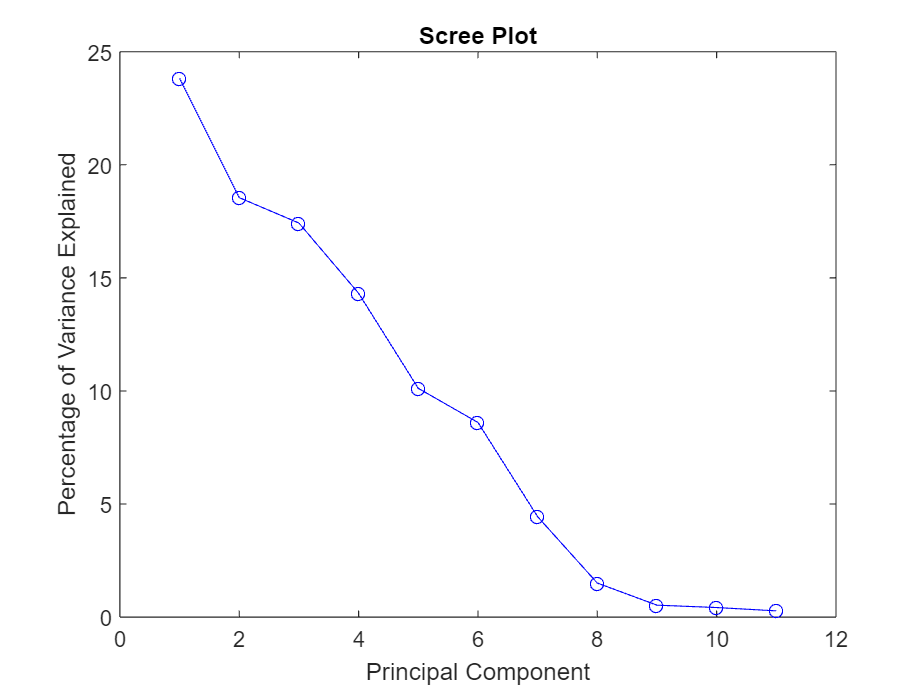

% Plot scree plot
plot(explained, 'bo-');
xlabel('Principal Component');
ylabel('Percentage of Variance Explained');
title('Scree Plot');

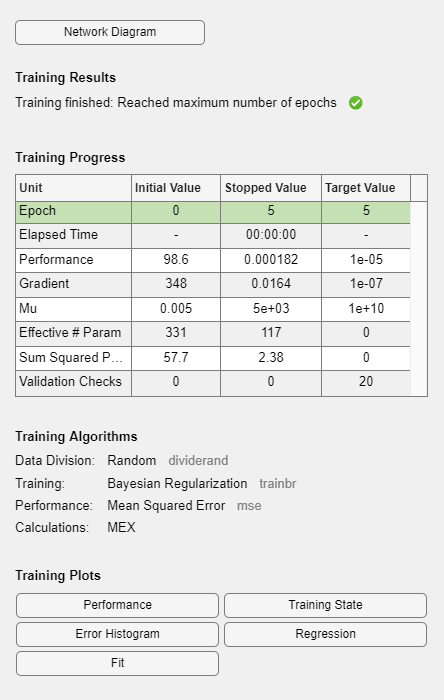

X = short_matrix_no_id;
Y = short_matrix_no_id(:,15);

% Train neural network
avg_accuracy = 0;
avg_MSE = 0;
avg_COV = 0;
n_cycle=50;

for i = 1:n_cycle
    % Split data into training and testing sets
    train_ratio = 0.5;
    train_size = round(train_ratio*size(X,1));
    train_idx = randperm(size(X,1),train_size);
    test_idx = setdiff(1:size(X,1),train_idx);
    X_train = X(train_idx,:);
    Y_train = Y(train_idx,:);
    X_test = X(test_idx,:);
    Y_test = Y(test_idx,:);

    % Define neural network
    input_size = size(X_train,2);
    output_size = 1;
    hidden_size = 15;
    net = fitnet(hidden_size);
    net.trainFcn = 'trainbr'; % Bayesian regulation algorithm
    net.divideFcn = 'dividerand'; % Random division of data into training and validation sets
    net.divideParam.trainRatio = 0.5; % Training set proportion
    net.divideParam.valRatio = 1 - net.divideParam.trainRatio; % Validation set proportion
    net.divideParam.testRatio = 0; % No testing set
    net.trainParam.max_fail = 20; % Maximum validation failures
    net.trainParam.epochs = 5; % Maximum number of epochs
    net.trainParam.goal = 1e-5; % Training goal
    net.performFcn = 'mse'; % Mean squared error performance function
    net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
        'plotregression', 'plotfit'};
    %train
    [net,tr] = train(net,X_train',Y_train');
    
    % Test neural network
    Y_pred = net(X_test');
    
    % Calculate the covariance error
    cov_error = sum(sum((cov(Y_pred) - Y_test).^2));
    avg_COV = avg_COV + cov_error;

    % Calculate the Accuracy and MSE
    acc = mean(abs(Y_pred-Y_test')<0.02);
    avg_accuracy = avg_accuracy + acc;
  
    avg_MSE = avg_MSE + mse(net,Y_pred,Y_test');
    
end

avg_accuracy = avg_accuracy/n_cycle;
avg_COV = avg_COV/n_cycle;
avg_MSE = avg_MSE/n_cycle;
%Display MSE, Accuracy and Covariance error.
disp('AVG ACCURACY: '+ avg_accuracy);

   65.2406   86.2406   71.2406   32.2406   65.2406   67.2406   67.2406   85.2406   82.2406   65.2406   67.2406   89.2406   58.2406   32.2406



disp('AVG MSE: '+ avg_MSE);

   65.1169   86.1169   71.1169   32.1169   77.1169   83.1169   69.1169   58.1169   32.1169



disp('AVG COV: '+ avg_COV);

   1.0e+04 *

    3.5179    3.5200    3.5185    3.5146    3.5181    3.5193    3.5200    3.5172    3.5146



% Display the covariance matrix
cov(Y_pred,Y_test)

ans =     6.0291    6.0322
    6.0322    6.0356
